fname = 'PD01_OFF_STN_L.txt'


   Neural State
  |-                                              -|
  ***********************************************

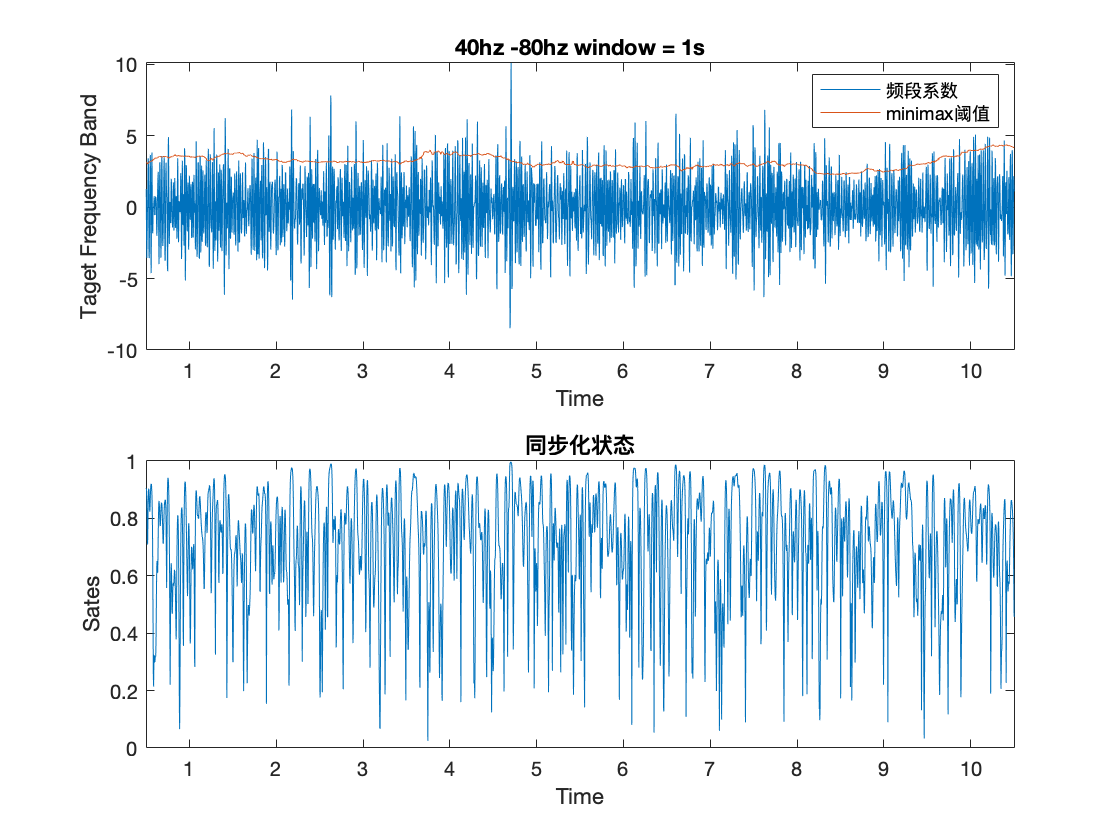

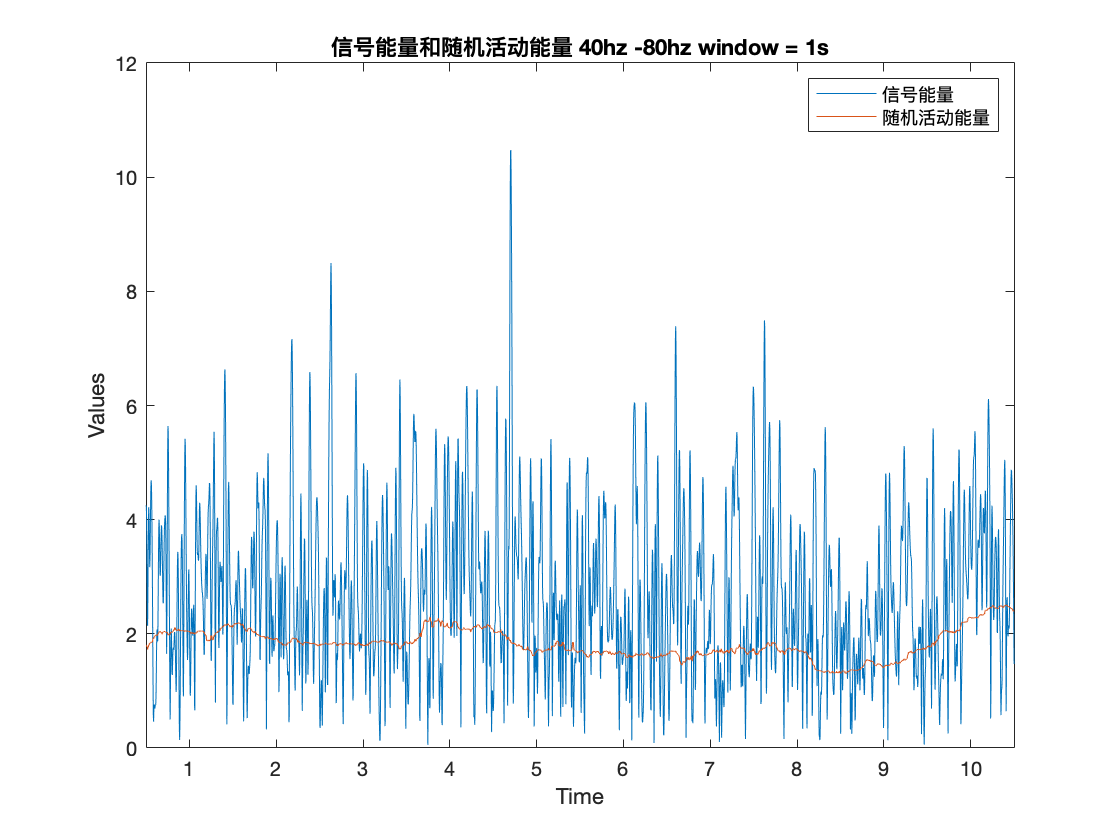

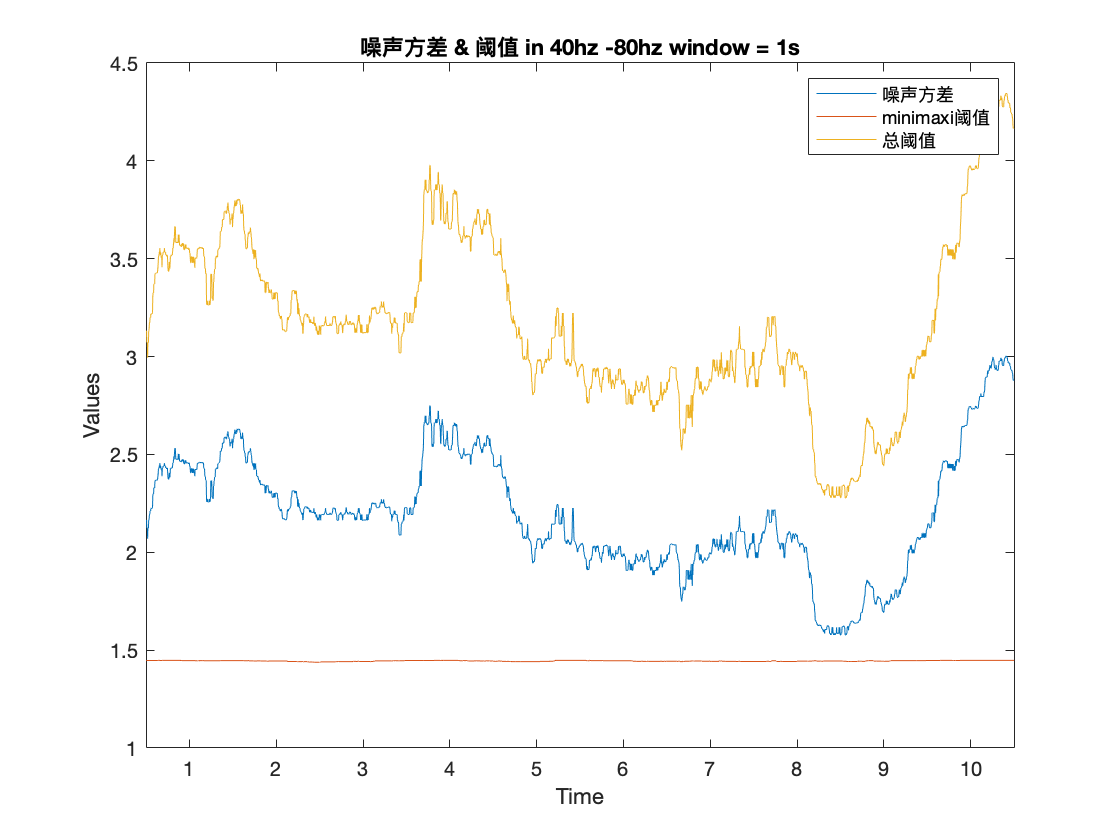


   Neural State
  |-                                              -|
  **********************************************

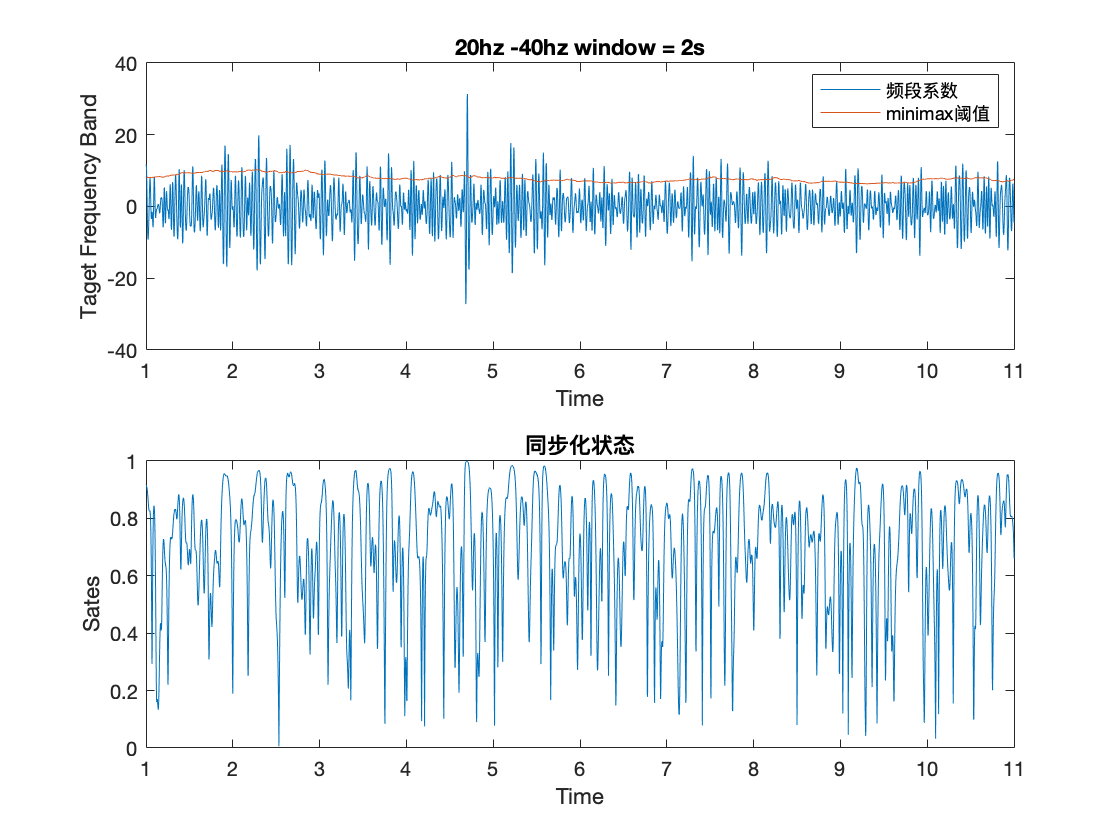

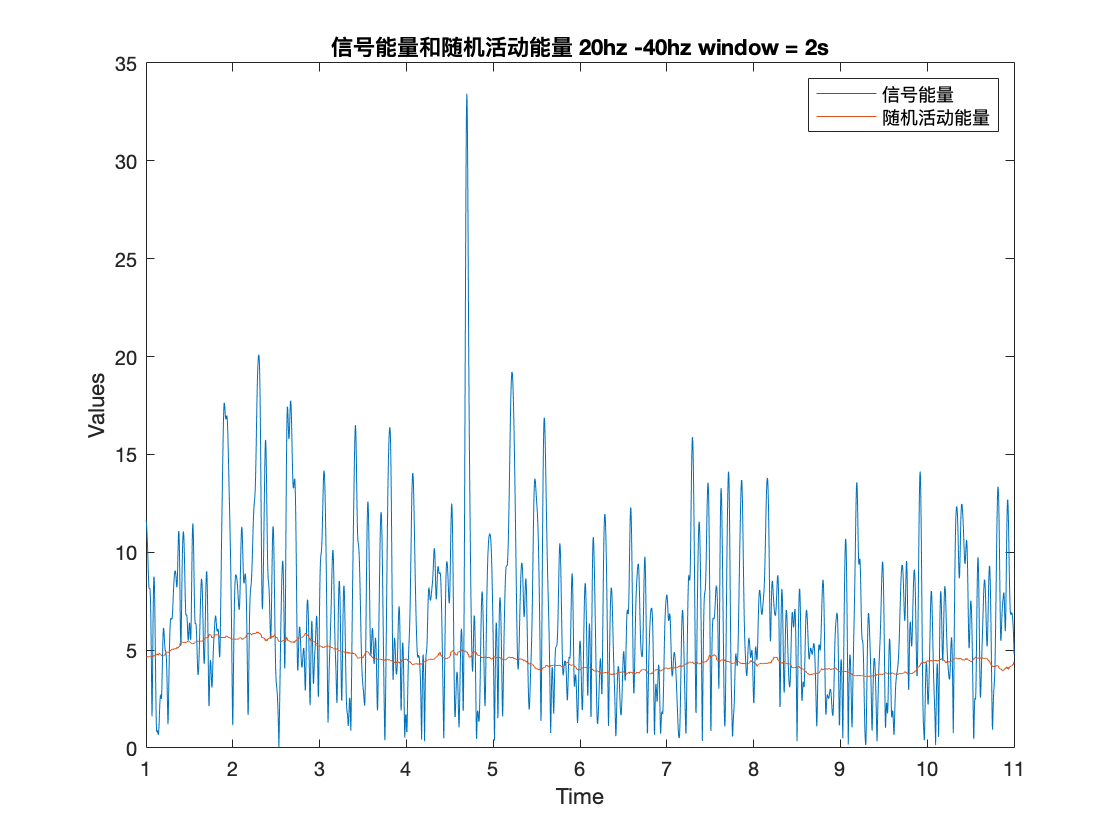

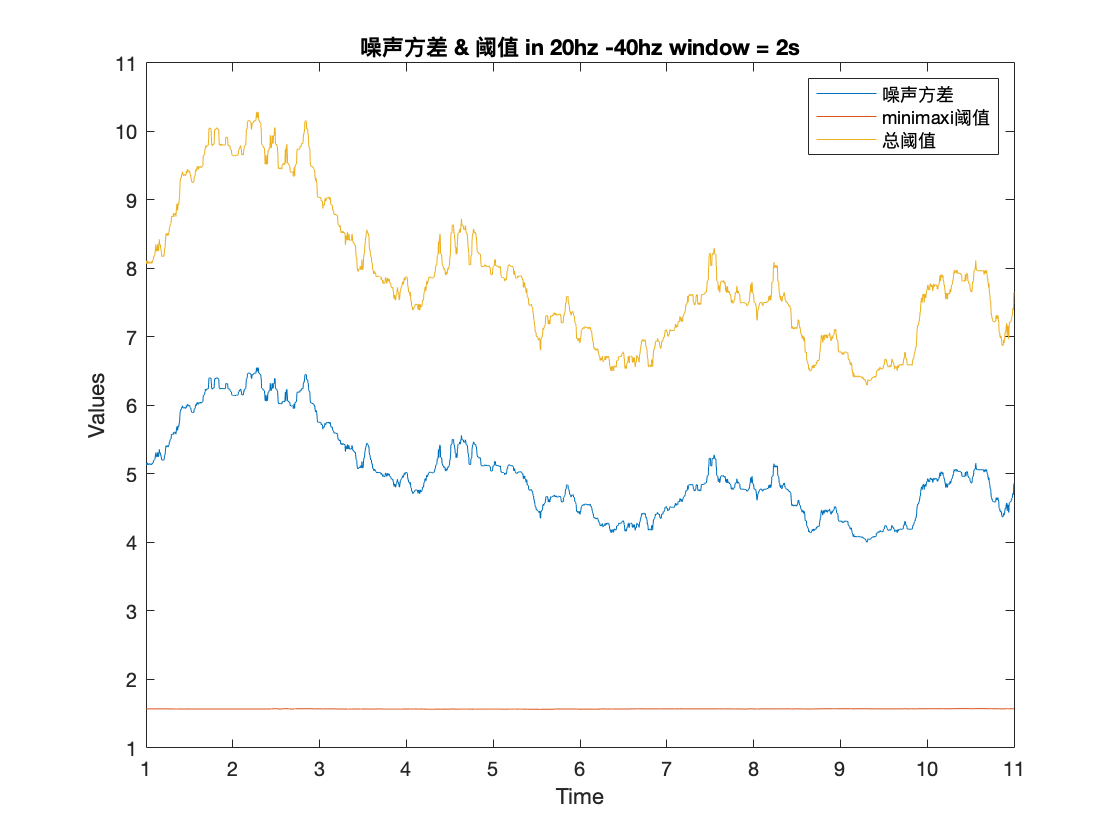


   Neural State
  |-                                              -|
  ********************************************

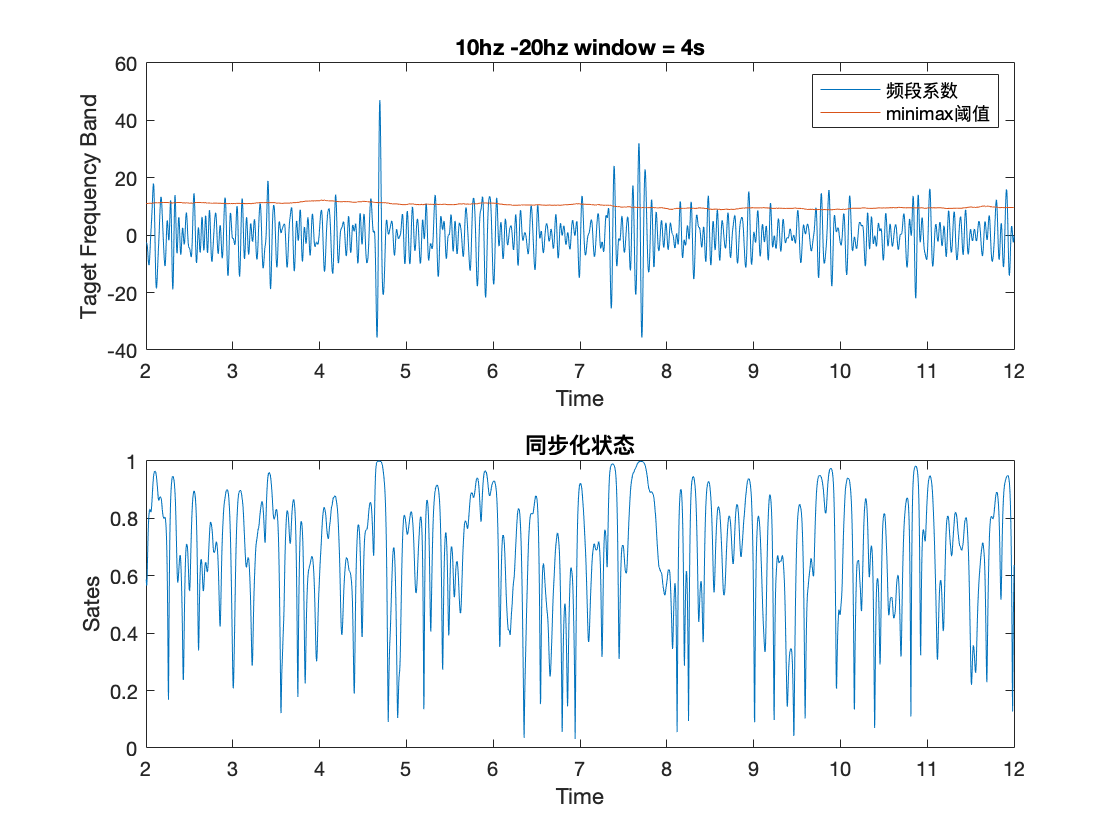

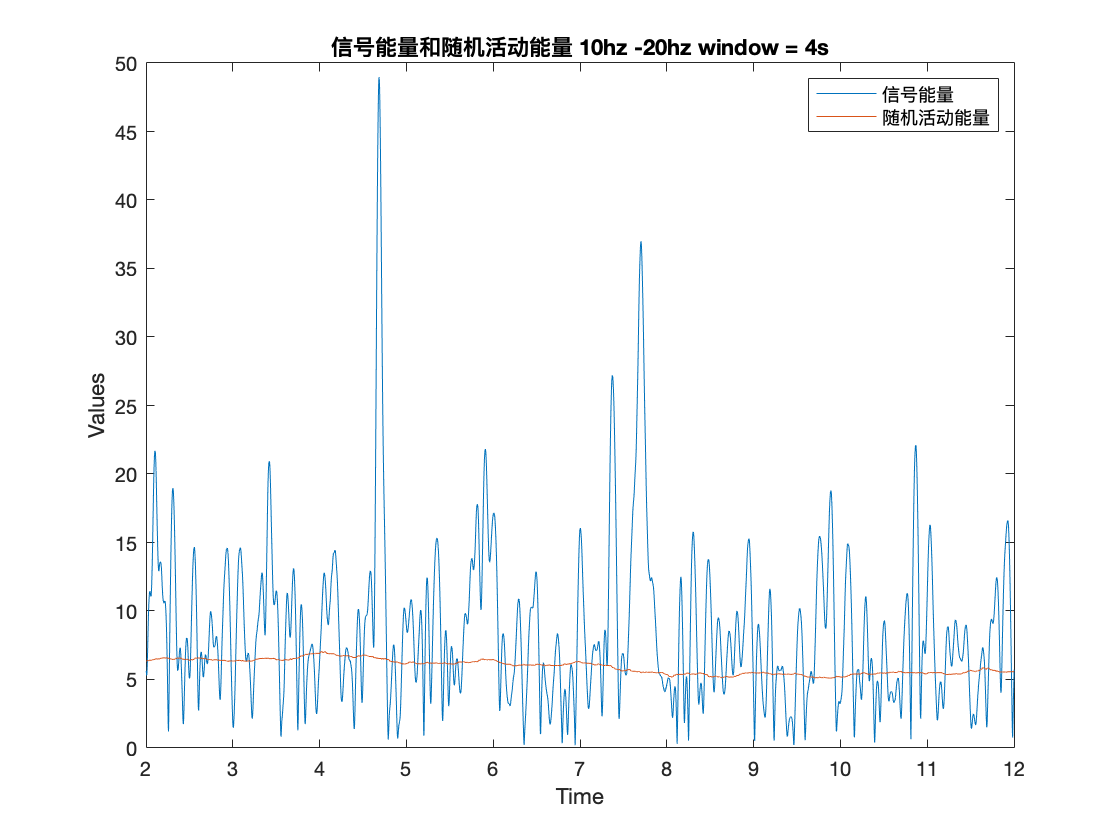

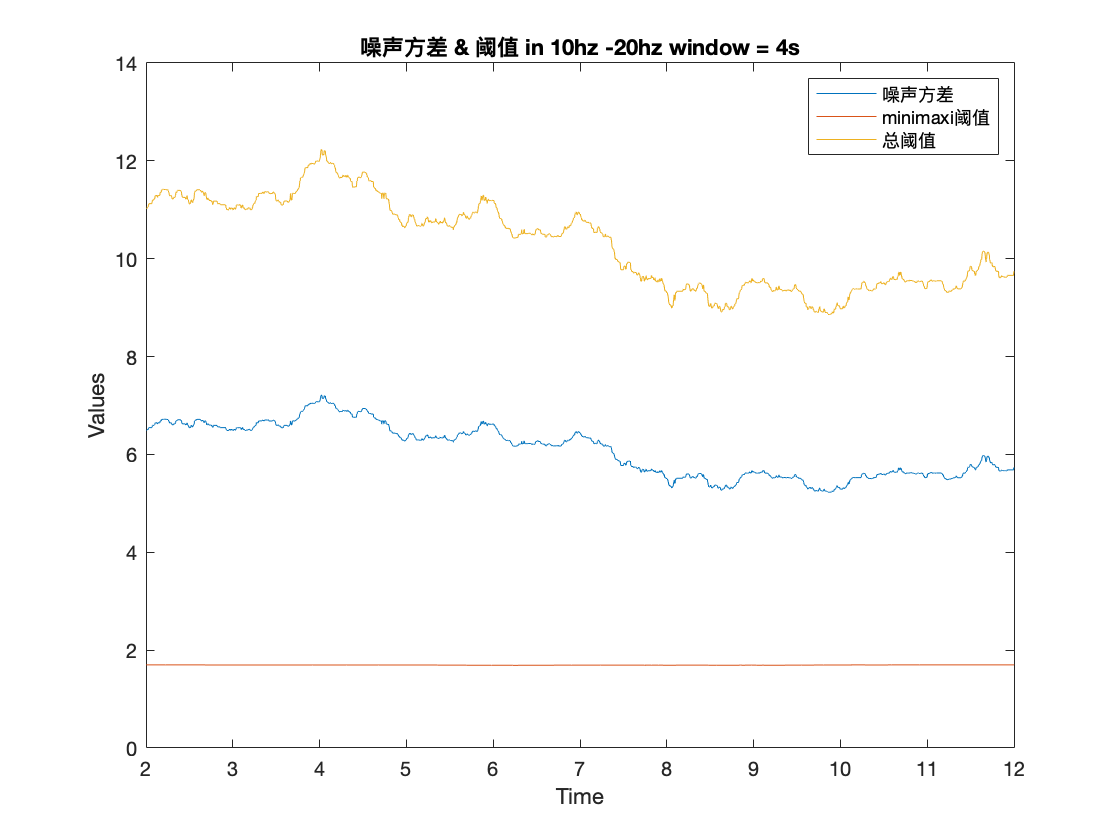


   Neural State
  |-                                              -|
  *****************************************

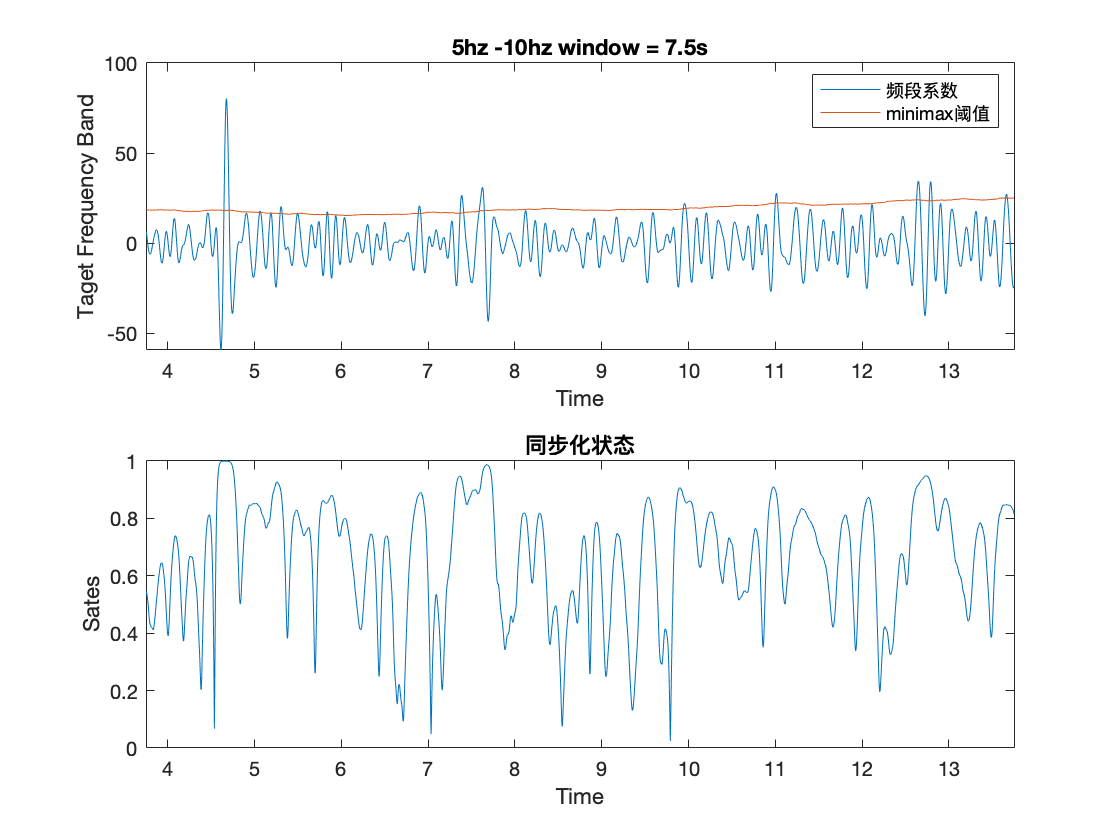

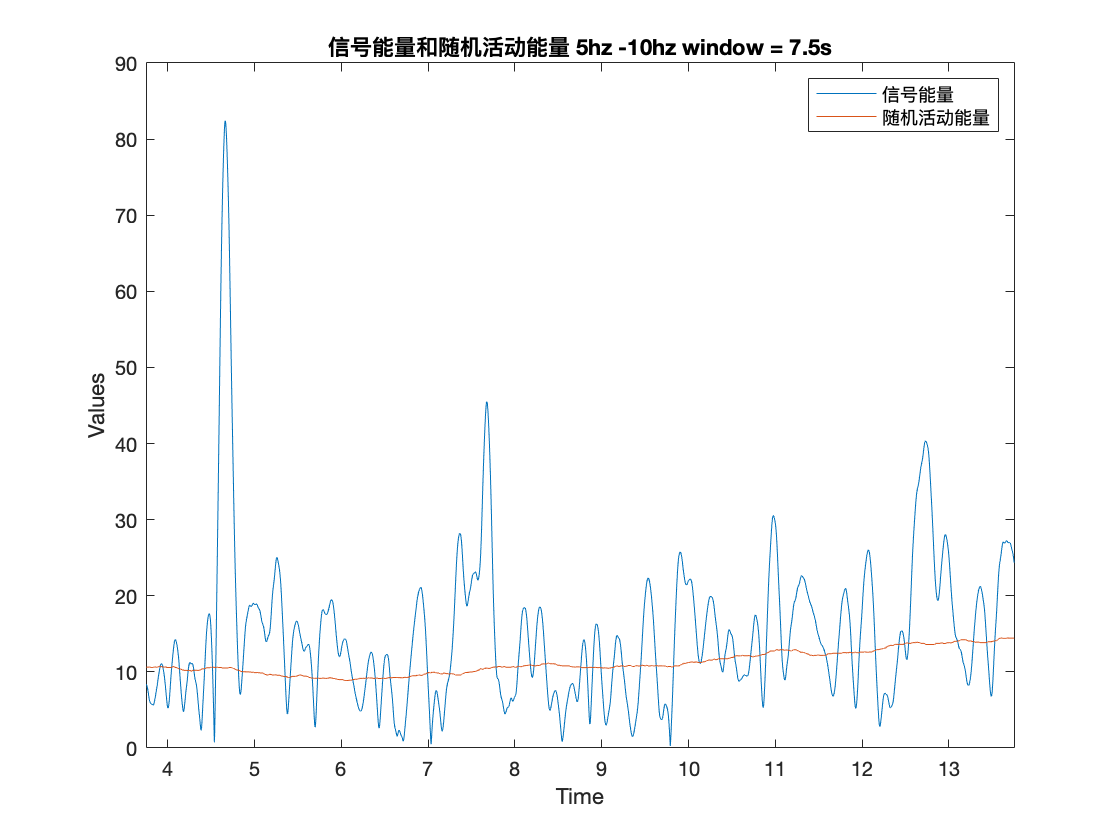

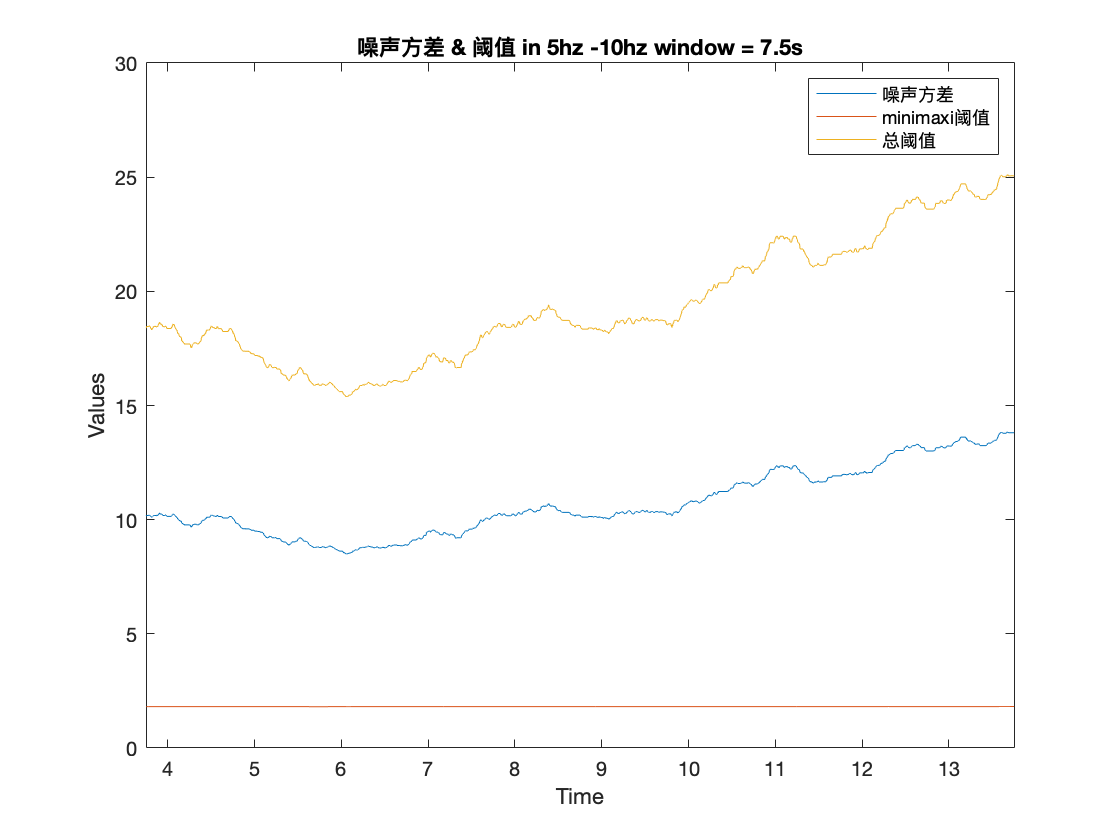

%写一个具体的流程图给老师

% 窗长和频率相关
% rigsure加平滑
% 2% control chart
% bayes threshold

clc; clear;
warning off;

fs=1000;%采样频率


% % load all files in selected folder
ftype='.txt';
pname='/Users/yskj/Desktop/项目/神经状态同步化/PDdata/';

txtfile = [pname,'*',ftype];
file  = dir(txtfile);
nside = size(file,1);
Mean  = zeros(1, nside);
Var   = zeros(1, nside);
ERROR = zeros(1, nside);
SynRatio = zeros(1, nside);
Burst = zeros(1, nside);

 
for iside=1:nside%21
%iside = 1;

fname=file(iside).name
impfilename=[pname,fname];
sori=importdata(impfilename,'\t',1);

for inode = 1:4
    %low beta & high beta的因果分析
    %这种因果关系和症状的联系：贝叶斯推断
    %
frequencyBand = inode+1; 
fsResample = 320;node=[6 frequencyBand];centralFreq = ceil((fsResample/2^(inode+1))*0.75);
startFreq = ceil((fsResample/2^(inode+1))*0.5);
endFreq = ceil((fsResample/2^(inode+1)));
%5-10:   fsResample = 320;node=[6 5];centralFreq = 7;
%10-20:  fsResample = 320;node=[6 4];centralFreq = 15;
%20-40:  fsResample = 320;node=[6 3];centralFreq = 30;
%40-80:  fsResample = 320;node=[6 2];centralFreq = 60;


%sgpi=sori.data(:,2);
%sgpiResample=resample(sgpi,fsResample,fs);
%signal = sgpiResample(fsResample*5:fsResample*10*60);
sSTN = sori.data;
sSTNResample=resample(sSTN,fsResample,fs);
signal = sSTNResample;


[states, tVector] = NeuralSynSWTSingle(signal, fsResample, node, centralFreq, startFreq, endFreq);

%{
figure;
h1 = histogram(states);
title(['Syncronization Metric Histogram window = ',num2str(1/centralFreq * 60),'s']);
%[c,lags] = xcorr(states);
%stem(lags,c)
%}

%{

Number = length(states);
windowNum = round(1/centralFreq * fsResample * 4);
step = round(0.02 * fsResample);
i = 1;
while(step*i+windowNum<Number)
    CurrentSignal = states(1+step*(i-1):step*(i-1)+windowNum);
    SignalSeg(i,:) = CurrentSignal;
    XHmm(i,:) = tVector(1+step*(i-1):step*(i-1)+windowNum);
    i = i+1;
end

[r,c]=size(SignalSeg); 
DataHmmCell = mat2cell(SignalSeg,r,c);

state_num = 3;
%p = 25;  % feature dim
[p_start, Prob, phi, loglik] = ChmmGauss(DataHmmCell, state_num);

% Calculate p(X) & vertibi decode
logp_xn_given_zn = Gauss_logp_xn_given_zn(DataHmmCell{1}, phi);
[~,~, loglik] = LogForwardBackward(logp_xn_given_zn, p_start, Prob);
path = LogViterbiDecode(logp_xn_given_zn, p_start, Prob);

color = ['k','r','b'];

figure;
SignalSeg = SignalSeg(1:400,:);
XHmm = XHmm(1:400,:);

[r,c]=size(SignalSeg);
for i = 1:r
    if mod(i,3)==2
        plot(XHmm(i,:),SignalSeg(i,:),'Color',color(path(i)));hold on;
    end
end
xlabel('Time/s');
ylabel('Synchronization States');
title('HMM States in 20-40hz');


figure;
xvalues = {'Black','Red','Blue'};
yvalues = {'Black','Red','Blue'};
cdata = reshape(Prob,3,3);
h = heatmap(xvalues,yvalues,cdata);
h.Title = 'Transition Probility';
h.XLabel = 'States';
h.YLabel = 'States';
%}

Mean(iside,inode) = mean(states);
Var (iside,inode) = var(states);
[A5, sgm5]  = ARLSS(states,5);
ERROR(iside,inode) = sgm5;
SynRatio(iside,inode) = length(find(states>0.7))/length(states);

states(states>0.7) = 1;
states(states<=0.7) = 0;
temp1 = [states,0];
temp2 = [0,states];
edge = temp1-temp2;
edge(end) = [];
onset = find(edge==1)*0.02;
offset = find(edge==-1)*0.02;
% Remove the last incomplete state
if ~isequal(size(onset),size(offset))
    onset(end) = [];
end
duration = offset-onset;
idx = duration<0.1;
onset(idx) = [];
offset(idx) = [];
duration = offset-onset;
Burst(iside,inode) = mean(duration);
end

end

BFMDRSTest = [22 22 16 16 16 16 11 11 36 36 27 27 12 12 29 29 24 24]

BFMDRSTest =     22    22    16    16    16    16    11    11    36    36    27    27    12    12    29    29    24    24


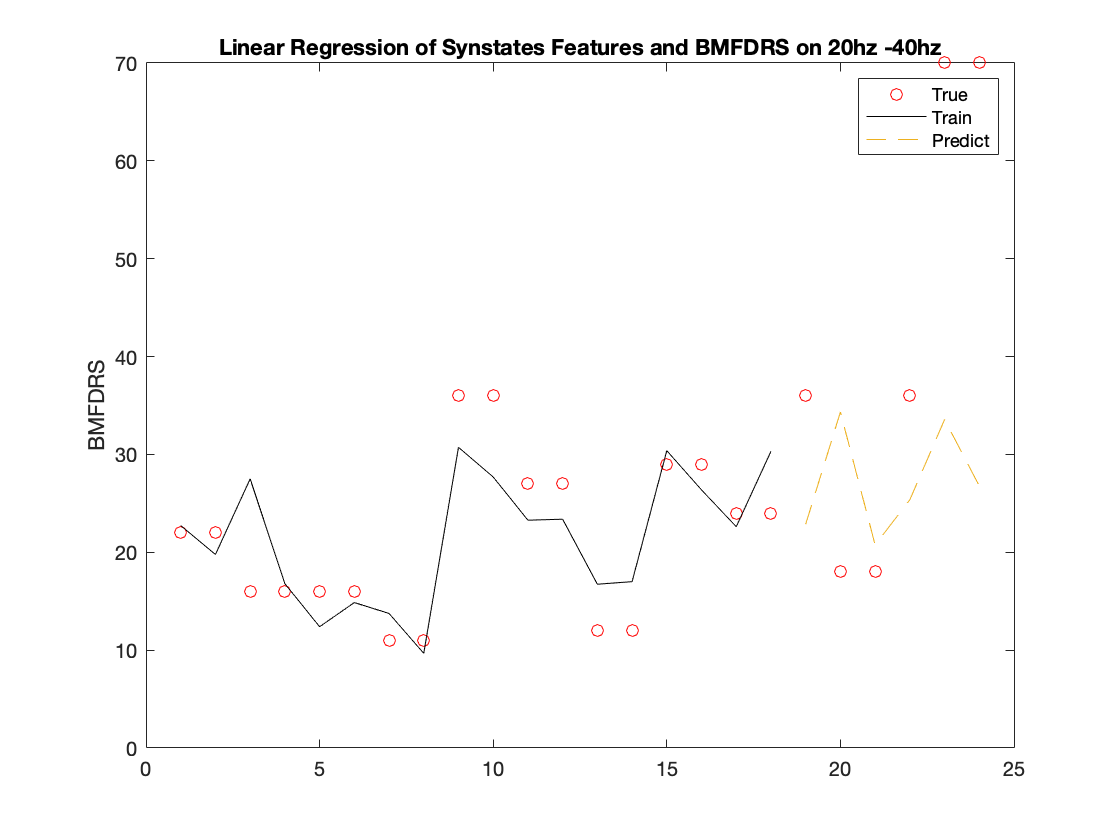

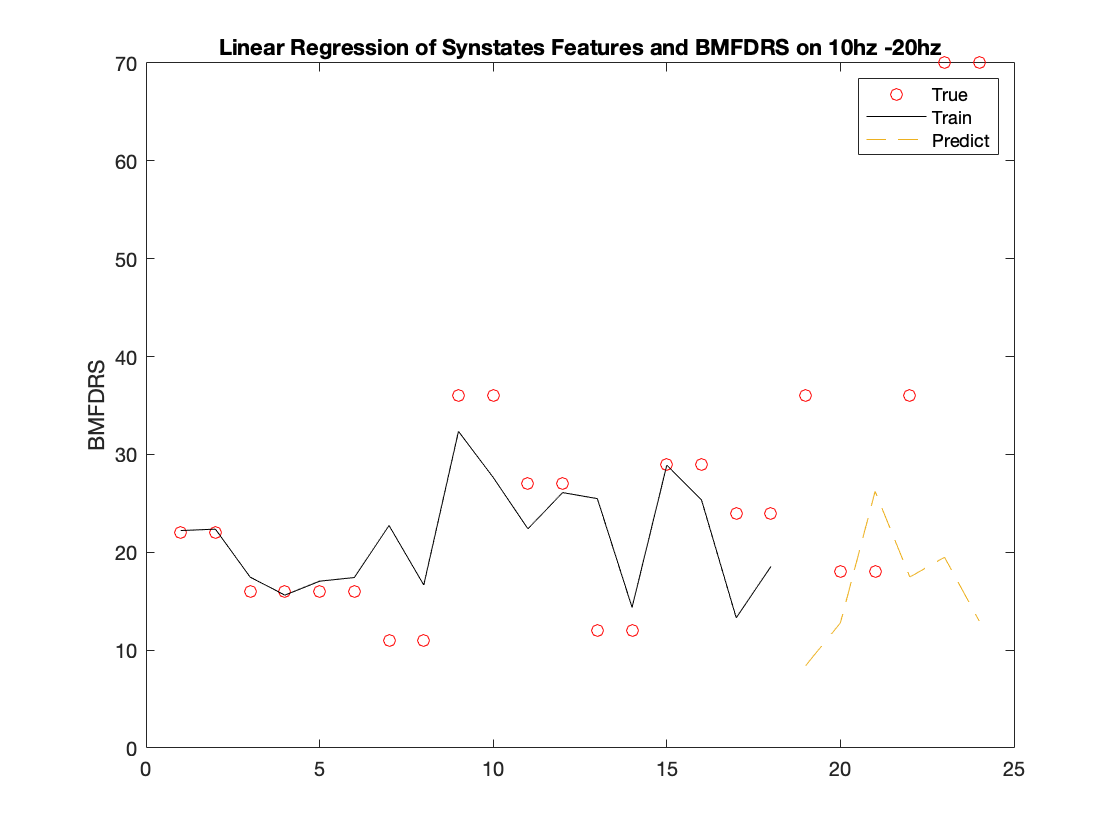

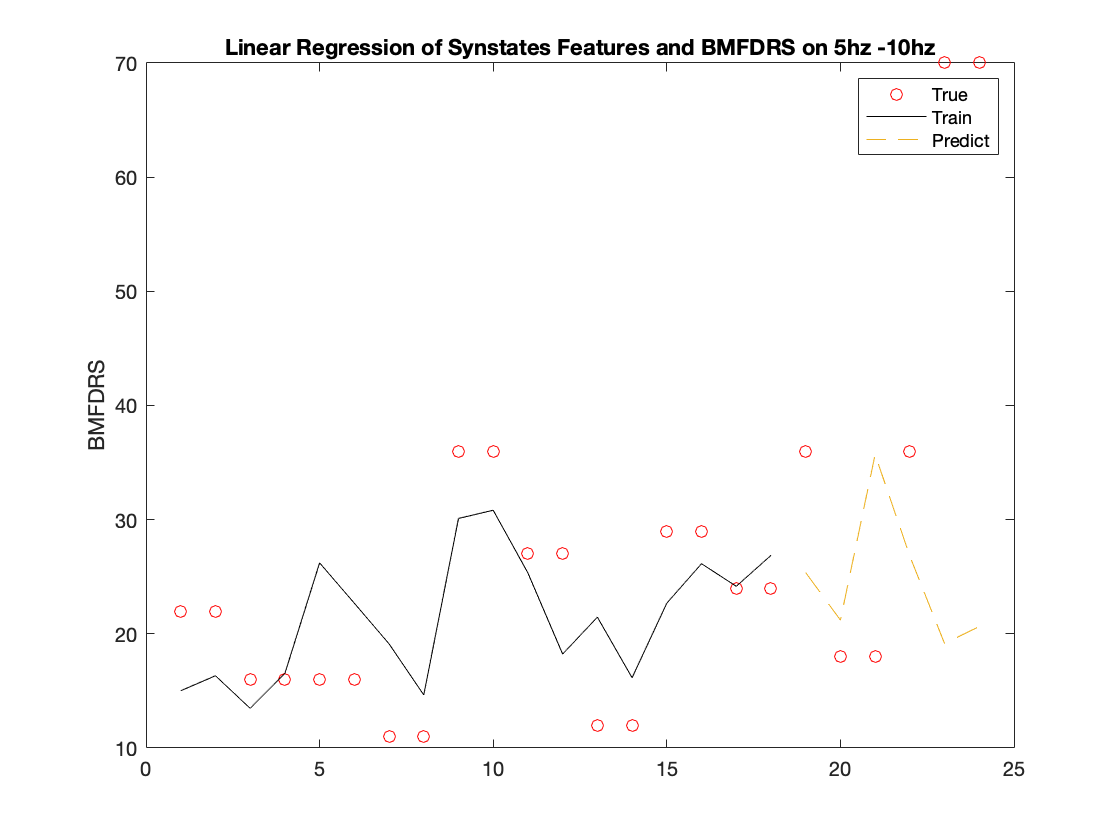

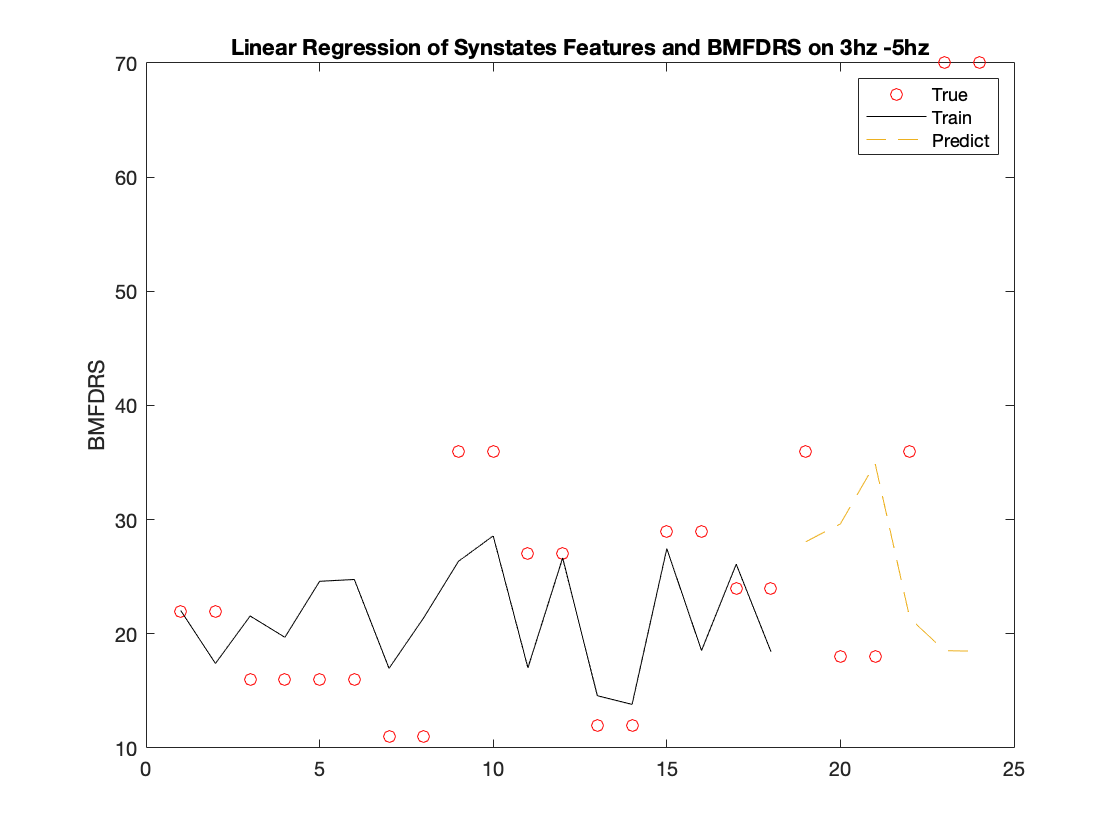

BFMDRsPred  = [36 18 18 36 70 70];%10min

%{
Test = [BFMDRS',Mean',Var', ERROR', SynRatio',Burst'];
[R,P]=corr(Test);
%}

for ifre = 1:4
    
fsResample = 320;
inode = ifre+2;
frequencyStart = ceil(fsResample/2^inode*0.5);
frequencyEnd   = ceil(fsResample/2^inode);

FeaturesTest = [ones(length(BFMDRSTest),1),Mean(1:end-6,ifre),Var(1:end-6,ifre), ERROR(1:end-6,ifre), SynRatio(1:end-6,ifre),Burst(1:end-6,ifre)];
FeaturesPred = [ones(length(BFMDRsPred),1),Mean(end-5:end,ifre),Var(end-5:end,ifre), ERROR(end-5:end,ifre), SynRatio(end-5:end,ifre),Burst(end-5:end,ifre)];

[b,bint,r,rint,stats] = regress(BFMDRSTest',FeaturesTest);
%rcoplot(r,rint)

%b2=[b(2),b(3),b(4),b(5),b(6)];
%Predict = b(1)+b2*FeaturesPred;
figure
Features = [Mean(:,ifre),Var(:,ifre), ERROR(:,ifre), SynRatio(:,ifre),Burst(:,ifre)];
BMFDRS = [BFMDRSTest,BFMDRsPred];
BMFDRS_fitting=b(1)+b(2)*Features(:,1)+b(3)*Features(:,2)+b(4)*Features(:,3)+b(5)*Features(:,4)+b(6)*Features(:,5);
X = 1:length(BMFDRS);
figure
plot(X, BMFDRS, 'ro');
hold on;
plot(X(1:end-6), BMFDRS_fitting(1:end-6)', 'k-');
hold on;
plot(X(end-5:end), BMFDRS_fitting(end-5:end)', '--');
hold off;
legend('True','Train','Predict')
ylabel('BMFDRS')
title(['Linear Regression of Synstates Features and BMFDRS on ',num2str(frequencyStart),'hz -',num2str(frequencyEnd),'hz'])


end

scatter3(Var,x2,BFMDRS,'filled') %scatter可用于画散点图
%拟合，三维视图显示
hold on  %在刚刚那副散点图上接着画
x1fit = min(x1):100:max(x1);   %设置x1的数据间隔
x2fit = min(x2):1:max(x2);     %设置x2的数据间隔
[X1FIT,X2FIT] = meshgrid(x1fit,x2fit);    %生成一个二维网格平面，也可以说生成X1FIT,X2FIT的坐标
YFIT=b(1)+b(2)*X1FIT.^2+b(3)*X2FIT.^2+b(4)*X1FIT + b(5)*X2FIT+b(6)*X1FIT.*X2FIT;    %代入已经求得的参数，拟合函数式
mesh(X1FIT,X2FIT,YFIT)    %X1FIT，X2FIT是网格坐标矩阵，YFIT是网格点上的高度矩阵
view(10,10)  %改变角度观看已存在的三维图，第一个10表示方位角，第二个表示俯视角。
%方位角相当于球坐标中的经度，俯视角相当于球坐标中的纬度
xlabel('x1') %设置X轴的名称
ylabel('x2') %设置y轴的名称
zlabel('y')  %设置z轴的名称


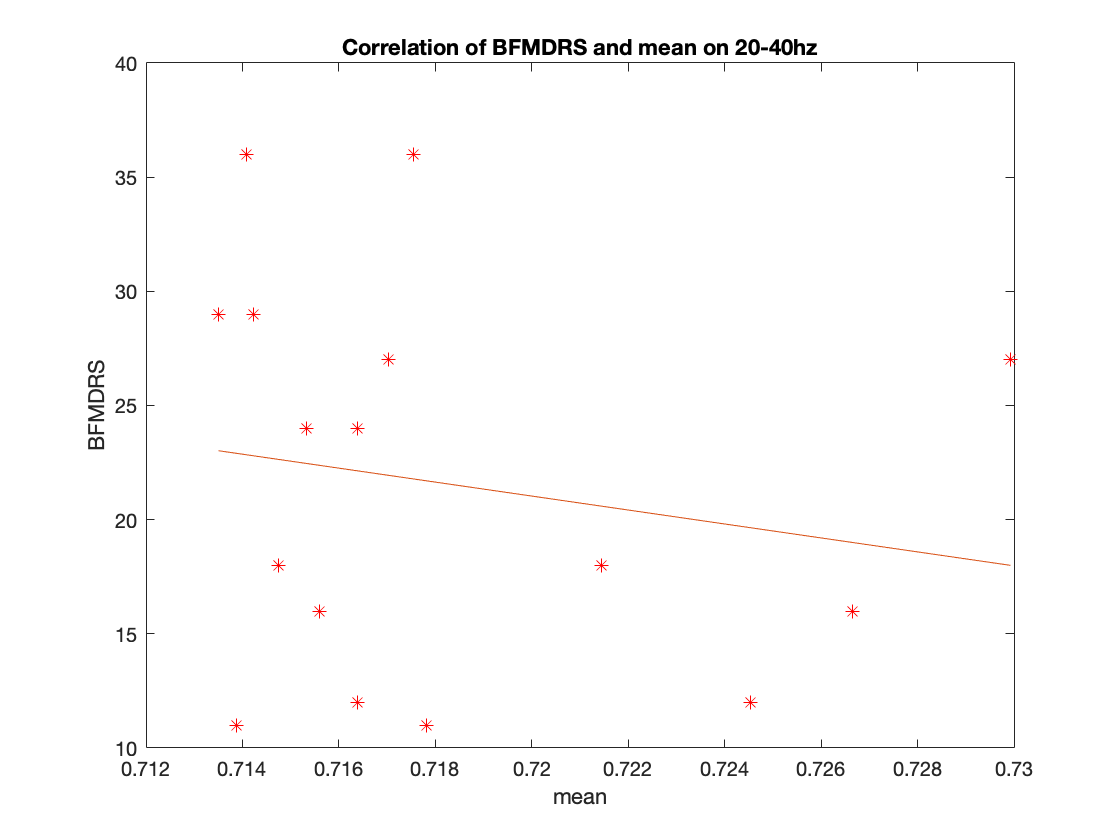

figure;
x = Mean';
y = BFMDRS';
plot(x,y,'r*');
hold on
%{
%回归分析
[b,bint,r,rint,stats]=regress(y,x);
%预测及作回归线图
z=b*x;
plot(x,z,'-');
xlabel('rate1'); % x轴注解
ylabel('BFMDRS'); % y轴注解
title('Correlation of BFMDRS and 4-8hz rate0'); % 图形标题
hold off;
%}

%回归分析
%[b,bint,r,rint,stats]=regress(y,x);
p = polyfit(x,y,1);
%预测及作回归线图
x = sort(x);
xi = linspace(min(x),max(x),30);
z = polyval(p,xi);
plot(xi,z,'-');
xlabel('mean'); % x轴注解
ylabel('BFMDRS'); % y轴注解
title('Correlation of BFMDRS and mean on 20-40hz'); % 图形标题
hold off;

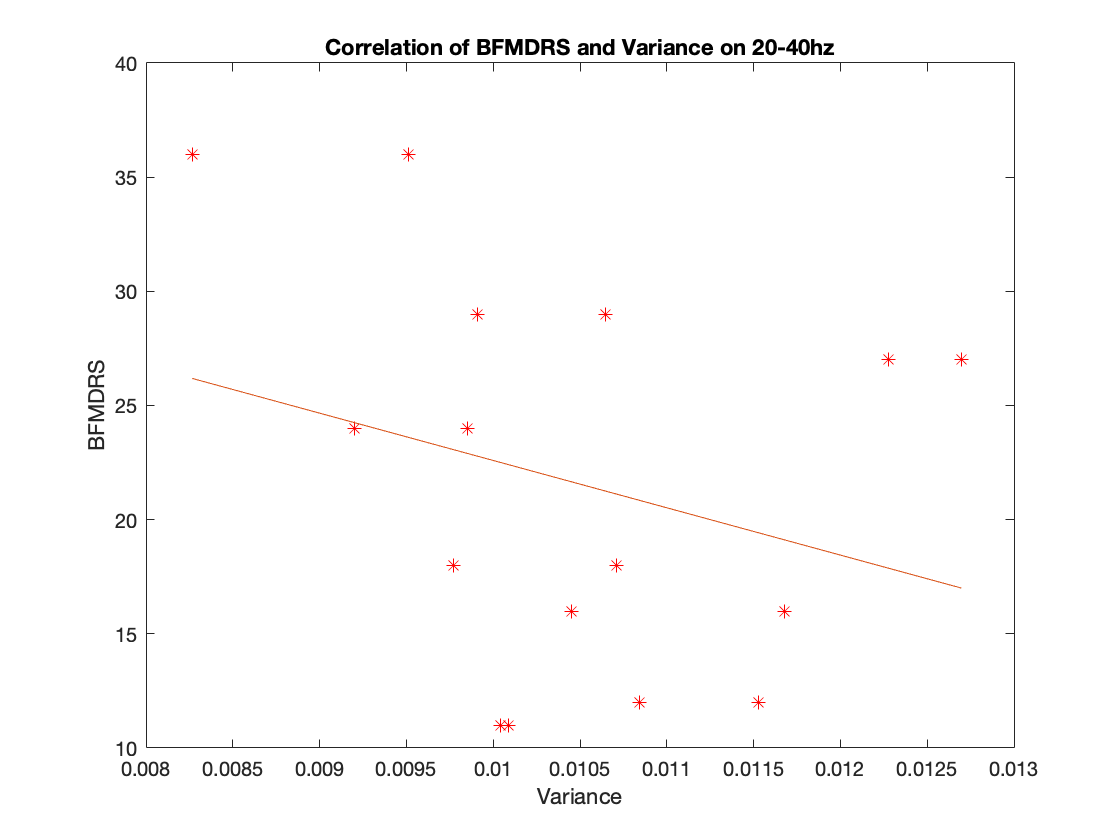


figure;
x = Var';
y = BFMDRS';
plot(x,y,'r*');
hold on
%{
%回归分析
[b,bint,r,rint,stats]=regress(y,x);
%预测及作回归线图
z=b*x;
plot(x,z,'-');
xlabel('rate1'); % x轴注解
ylabel('BFMDRS'); % y轴注解
title('Correlation of BFMDRS and 4-8hz rate0'); % 图形标题
hold off;
%}

%回归分析
%[b,bint,r,rint,stats]=regress(y,x);
p = polyfit(x,y,1);
%预测及作回归线图
x = sort(x);
xi = linspace(min(x),max(x),30);
z = polyval(p,xi);
plot(xi,z,'-');
xlabel('Variance'); % x轴注解
ylabel('BFMDRS'); % y轴注解
title(['Correlation of BFMDRS and Variance on 20-40hz']); % 图形标题
hold off;

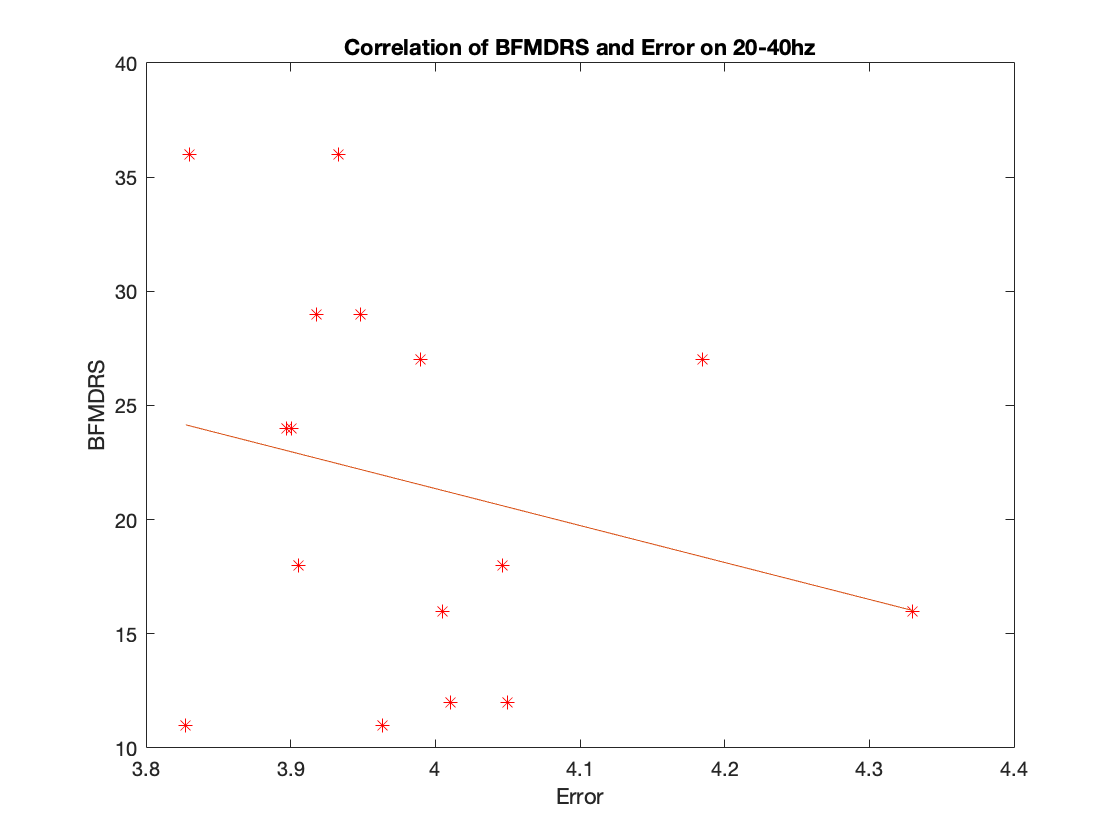



figure;
x = ERROR';
y = BFMDRS';
plot(x,y,'r*');
hold on
%{
%回归分析
[b,bint,r,rint,stats]=regress(y,x);
%预测及作回归线图
z=b*x;
plot(x,z,'-');
xlabel('rate1'); % x轴注解
ylabel('BFMDRS'); % y轴注解
title('Correlation of BFMDRS and 4-8hz rate0'); % 图形标题
hold off;
%}

%回归分析
%[b,bint,r,rint,stats]=regress(y,x);
p = polyfit(x,y,1);
%预测及作回归线图
x = sort(x);
xi = linspace(min(x),max(x),30);
z = polyval(p,xi);
plot(xi,z,'-');
xlabel('Error'); % x轴注解
ylabel('BFMDRS'); % y轴注解
title('Correlation of BFMDRS and Error on 20-40hz'); % 图形标题
hold off;

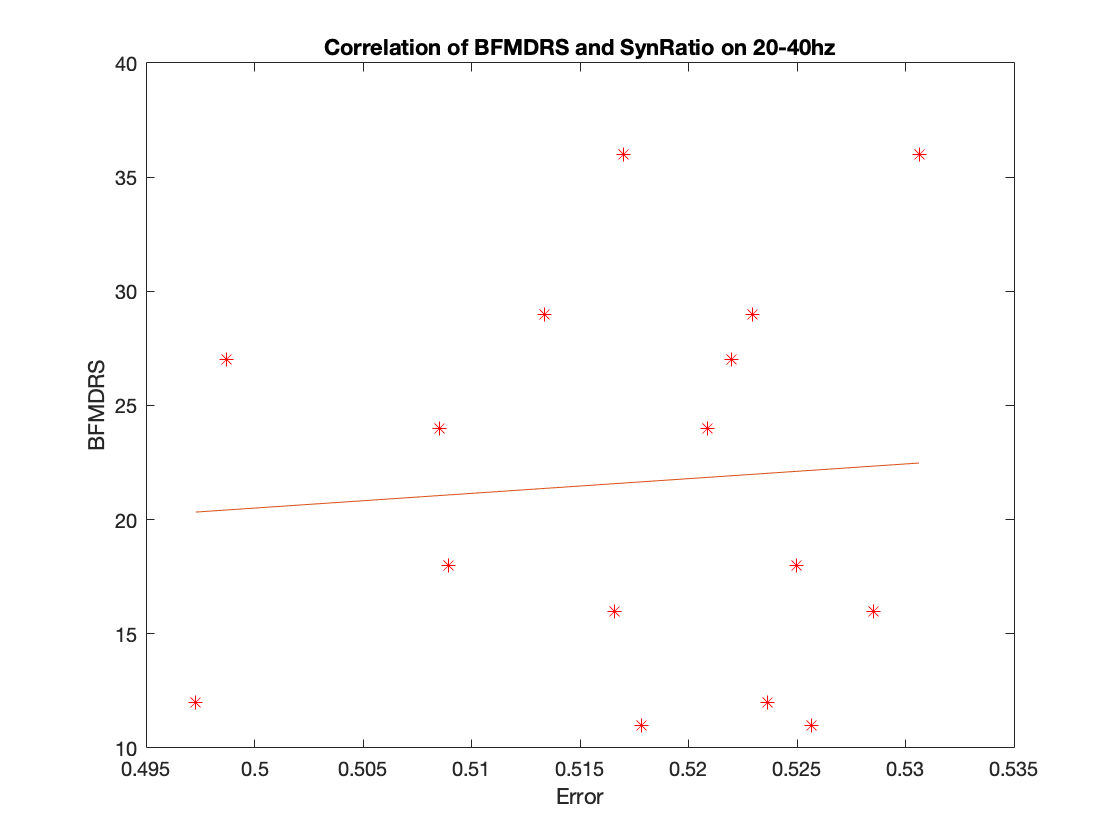



figure;
x = SynRatio';
y = BFMDRS';
plot(x,y,'r*');
hold on
%{
%回归分析
[b,bint,r,rint,stats]=regress(y,x);
%预测及作回归线图
z=b*x;
plot(x,z,'-');
xlabel('rate1'); % x轴注解
ylabel('BFMDRS'); % y轴注解
title('Correlation of BFMDRS and 4-8hz rate0'); % 图形标题
hold off;
%}

%回归分析
%[b,bint,r,rint,stats]=regress(y,x);
p = polyfit(x,y,1);
%预测及作回归线图
x = sort(x);
xi = linspace(min(x),max(x),30);
z = polyval(p,xi);
plot(xi,z,'-');
xlabel('Error'); % x轴注解
ylabel('BFMDRS'); % y轴注解
title('Correlation of BFMDRS and SynRatio on 20-40hz'); % 图形标题
hold off;